# Homework 5: Dielectric Slab Waveguide 

**    Resources:** 

- *Semiconductor Optoelectronic Ch.8 *Farham Rana, Cornell University, 

- *Electromagnetic Wave Theory Ch.4 *Jin Au Kong (2008)

In this tutorial we will solve for and plot the modes of a dielectric slab waveguide. We will gain hands on experience solving for the eigenmode solutions of the electric field, learn about the odd and even modes, and get experience plotting and interpretting a dispersion diagram. 

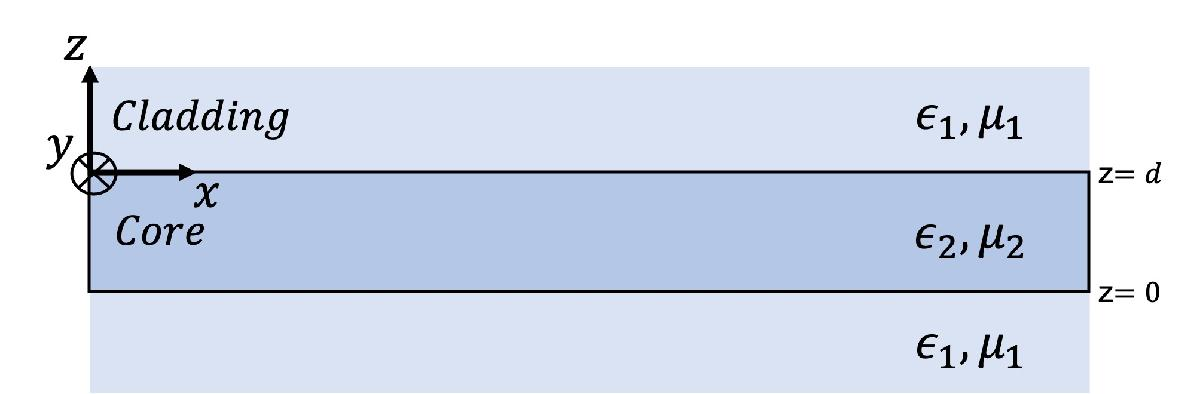

**Figure 1 **A dielectric slab waveguide in a symmetric environment

*A note on conventions: *

- In this tutorial vectors are bolded $\mathit{\mathbf{E}}=\vec{E} =\left(E_x ,E_y ,E_z \right)$

- The subscript on the field, ${\mathit{\mathbf{E}}}_{\mathit{\mathbf{i}}} \;,$ indicates which material it is in where $i=1\;\textrm{is}\;\textrm{cladding},i=2\;\textrm{is}\;\textrm{core}$

- We are looking at a field pattern that varies sinusoidally in time with $e^{-i\omega \;t}$ time dependence.

The Wave Equation:

    
$$\nabla \times \nabla \times E_i =\frac{\omega^2 }{c^2 }n_i^2 E_i$$


## Part 0

## Identify the eigenproblem

In this tutorial we are solving for the TE (s-polarized) modes of the waveguides. Recall that TE means "transverse electric", so in our diagram above, we will assume that the electric field is in the $\hat{y} \;$direction. Additionally we will assume propagation in the $x$-direction in the waveguide. Thus, we will assume that our solutions are of the form $E\left(x,z\right)=\hat{y} \;E_0 \;\phi \;\left(z\right)\;e^{{\textrm{ik}}_x x}$ where $E_0$ is a constant and $\phi \;\left(z\right)$ is the mode profile.

#### (a) Plug this mode solution into the wave equation to obtain an eigenvalue equation of the form $\hat{O} \phi \;\left(z\right)=\lambda \;\phi \left(z\right)$, where $\hat{O}$ is an operator.

[Fill in here or ok to do on a seperate doc and submit as a PDF]

% MATLAB script to solve for the TE mode eigenvalue equation
syms z beta k0 n(z) omega t x phi(z)

% 1. Define the mode solution form for the electric field
E_y = phi(z) * exp(1i * (beta * x - omega * t));

% 2. Scalar wave equation for TE modes
% Wave equation: Laplacian(E) + k0^2 * n(z)^2 * E = 0
% In this 1D profile, Laplacian = d2/dx2 + d2/dz2
d2E_dx2 = diff(E_y, x, 2);
d2E_dz2 = diff(E_y, z, 2);

wave_eq = d2E_dx2 + d2E_dz2 + (k0^2 * n(z)^2) * E_y == 0;

% 3. Simplify by dividing out the common exponential term
% This isolates the mode profile phi(z)
simplified_eq = simplify(wave_eq / exp(1i * (beta * x - omega * t)));

% 4. Rearrange into the eigenvalue form: O * phi = lambda * phi
% where lambda = beta^2
% O * phi = (d2/dz2 + k0^2 * n^2) * phi
lhs = diff(phi, z, 2) + (k0^2 * n(z)^2) * phi(z);
rhs = beta^2 * phi(z);

disp(lhs == rhs);

$$\frac{\partial^{2}}{\partial z^{2}}\varphi \left(z\right)+\varphi \left(z\right)\,{k_{0}}^{2}\,{n\left(z\right)}^{2}=\beta^{2}\,\varphi \left(z\right)$$

## 
$$r = \frac{k_z - i\alpha}{k_z + i\alpha}
$$


## Part 1

## Determine the Guidance Condition of the TE mode

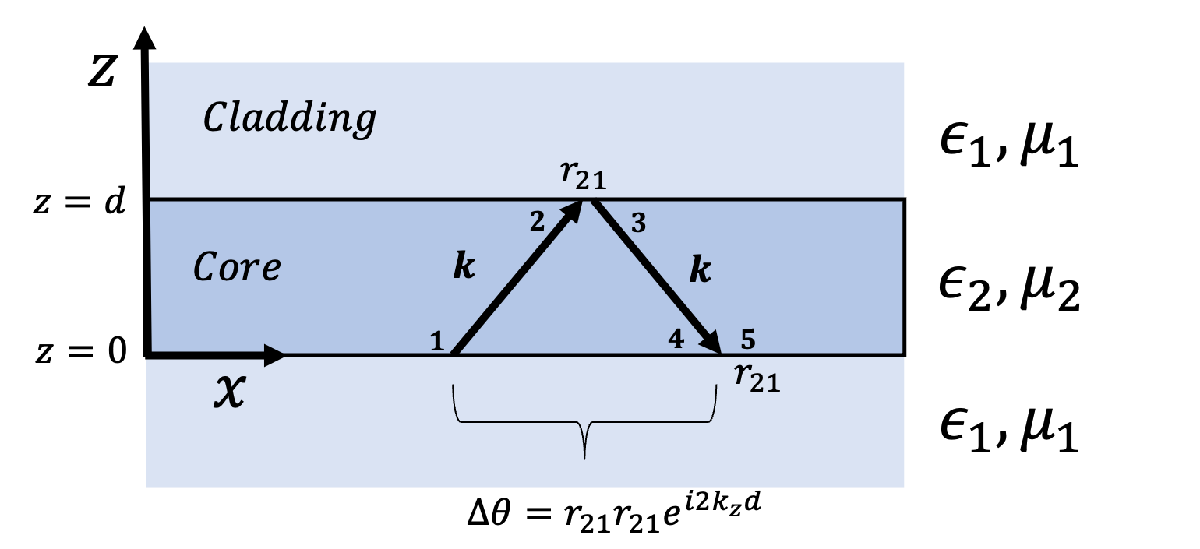

**Figure 2 **Illustration of guidance condition via total internal reflection phase accumulation argument

A guided mode is due to the coherent or constructive interferance of waves upon internal reflection within the waveguide. For waves to add coherently they must be at the same phase at the same position. Let's consider the phase of the wave as it transverses the waveguide in the x-direction and is reflected off either side and determine under what condition constructive infererence will occur:

Starting as the bottom interface of the waveguide, upon traversing the width of the waveguide, d, the wave aquires a phase of $e^{{\textrm{ik}}_z d}$. Reflecting off the top interface it aquires a reflection coefficient $r_{\textrm{top}}$. It then traverses again back to the right side, acquiring an additional $e^{{\textrm{ik}}_z d}$ phase and then is reflected off the right interface, aquiring the reflection coefficient $r_{\textrm{bottom}} \ldotp$ Thus, to have the same phase as the wave at the original position $e^{{\textrm{i2dk}}_z } r_{\textrm{top}} r_{\textrm{bottom}} =1$must be true. The reflection coefficients $r_{\textrm{top}} ,r_{\textrm{bottom}}$ depend on the optical properties of the materials. In our case, the cladding on the top and bottom of the core is identical, so we assume $r_{\textrm{top}} =r_{\textrm{bottom}} =r_{21}$. Thus, our guidance condition is $e^{{\textrm{i2dk}}_z } r_{21}^2 =1$

#### (a) Recalling your work from Demo #2, what is the reflection cofficient, $r_{21}$, at the core-cladding interface for the TE polarization (s-polarization)? 

#### (Hint: In this case the z-component of the E-ield in the cladding is evanescent, so the wavevector is imaginary $\left(k_{z,\textrm{transmitted}} =k_{z,\textrm{cladding}} =\pm i\gamma_z \right)$. The z-component of the wavevector inside the core is real and we will call it simply $k_z$).

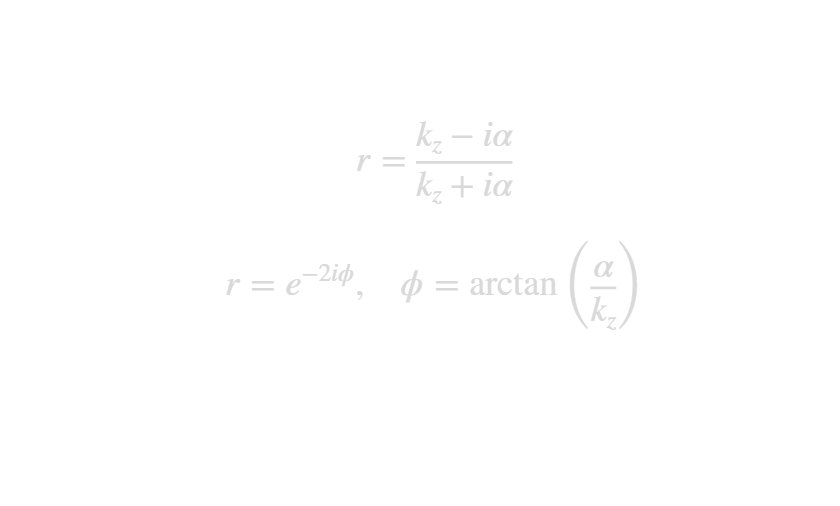


% Define the reflection coefficient formula
r_latex = 'r = \frac{k_z - i\alpha}{k_z + i\alpha}';

% Define the phase-shifted form
r_phase_latex = 'r = e^{-2i \phi}, \quad \text{where} \quad \phi = \arctan\left(\frac{\alpha}{k_z}\right)';

% Use this string to avoid the SceneNode error
r_formula = '$r = \frac{k_z - i\alpha}{k_z + i\alpha}$';

% Phase shift version (simplified for MATLAB's interpreter)
r_phase = '$r = e^{-2i \phi}, \quad \phi = \arctan\left(\frac{\alpha}{k_z}\right)$';

% Displaying in a figure
figure('Color', 'w');
axis off;
text(0.5, 0.7, r_formula, 'Interpreter', 'latex', 'FontSize', 18, 'HorizontalAlignment', 'center');
text(0.5, 0.4, r_phase, 'Interpreter', 'latex', 'FontSize', 18, 'HorizontalAlignment', 'center');

*Your solution to part (a) should be in the form of $\frac{a-ib}{a+ib}$. Note that $\frac{a-ib}{a+ib} = e^{i\phi}$where $\phi =-{2\tan }^{-1} \left(\frac{b}{a}\right)$.

#### (b) With the guidance condition that we gave you and your answer for (a), show that the condition on the values of d and $\phi$ to gaurentee guidance in the waveguide is $2dk_z +2\phi =2m\pi$, where $\phi =-{2\tan }^{-1} \left(\frac{\gamma_z }{k_z }\right)$

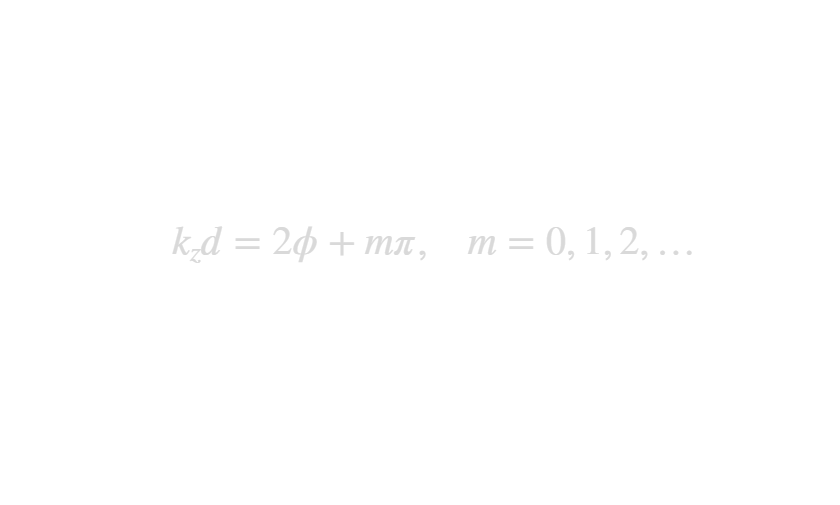

% Final Guidance Condition LaTeX
guidance_eqn = '$k_z d = 2\phi + m\pi, \quad m = 0, 1, 2, \dots$';

figure('Color', 'w');
axis off;
text(0.5, 0.5, guidance_eqn, 'Interpreter', 'latex', 'FontSize', 20, 'HorizontalAlignment', 'center');

## Even and odd guided modes

We've shown the guidance condition to be $2dk_z +2\phi =2m\pi$, where $\phi =-2\tan^{-1} \left(\frac{\gamma_z }{k_z }\right)$ (if you haven't gotten to this solution check the references shared above). We can rewrite this equation as follows:


$$2dk_z +2\phi =2m\pi$$



$$2dk_z -4tan^{-1}\Big(\frac{\gamma_z}{k_z}\Big) =2m\pi$$



$$tan\Big(\frac{dk_z}{2} - \frac{m\pi}{2}\Big) 
= \Big(\frac{\gamma_z}{k_z}\Big)$$


If m is even:


$$tan\Big(\frac{dk_z}{2} \Big) 
= \Big(\frac{\gamma_z}{k_z}\Big)$$


if m is odd:


$$-cot\Big(\frac{dk_z}{2} \Big)
= \Big(\frac{\gamma_z}{k_z}\Big)$$


These are the guidance conditions for the waveguide for *even* and *odd *modes. This means that these relationships between d, $k_z ,$ and $\gamma_z$ *must *exist in order for a mode to propogate.

## Part 2

## Solve for the waveguide modes

So far we have identified the guidance conditions for even and odd modes in the waveguide, but this is not enough to solve for the dispersion relation of the waveguide system. We need another constraint which we can use to solve for the mode solutions *graphically*. 

#### (a) Using the material dispersion relations for the core and cladding, show that $\frac{\omega^2 }{c^2 }\mu \;\left(\epsilon_2 -\epsilon_1 \right)d^2 ={\left(\gamma_z \;d\right)}^2 +{\left(k_z d\right)}^2$ 

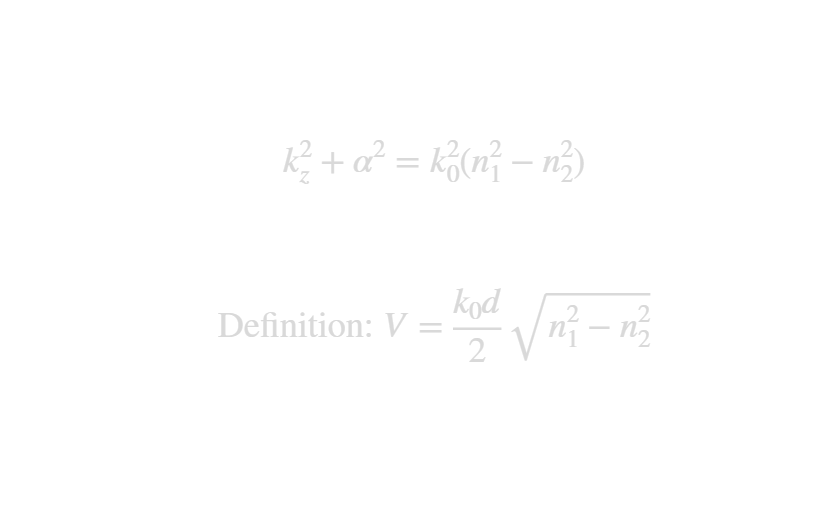

% Circle Constraint LaTeX for MATLAB
constraint_latex = '$k_z^2 + \alpha^2 = k_0^2 (n_1^2 - n_2^2)$';
v_number_latex = '$V = \frac{k_0 d}{2} \sqrt{n_1^2 - n_2^2}$';

figure('Color', 'w');
axis off;
text(0.5, 0.7, constraint_latex, 'Interpreter', 'latex', 'FontSize', 18, 'HorizontalAlignment', 'center');
text(0.5, 0.3, ['Definition: ', v_number_latex], 'Interpreter', 'latex', 'FontSize', 18, 'HorizontalAlignment', 'center');

You now have three equations which, combined, solve for the even and odd modes of the slab waveguide

- 
$$\frac{\omega^2 }{c^2 }\mu \;\left(\epsilon_2 -\epsilon_1 \right)d^2 ={\left(\gamma_z \;d\right)}^2 +{\left(k_z \;d\right)}_{\;}^2$$
     

- $tan\Big(\frac{dk_z}{2} \Big) 
= \frac{\gamma_z}{k_z}$            (odd modes)

- $-cot\Big(\frac{dk_z}{2} \Big)
= \Big(\frac{\gamma_z}{k_z}\Big)$     (even modes)

Next we will solve for these modes graphically and then implement this in code to create our dispersion relations for the even and odd modes.

#### (b) *Graphical Solution: *Plot the following three equations on the axis $\frac{k_z d}{2}\;\textrm{vs}\ldotp \;\frac{\gamma_z }{k_z }$ at a reasonable value of $\omega$ so that multiple modes are supported. 

- 
$$\frac{\omega^2 }{c^2 }\mu \;\left(\epsilon_2 -\epsilon_1 \right)d^2 ={\left(\gamma_z \;d\right)}^2 +{\left(k_z d\right)}^2$$
 

- 
$$tan\Big(\frac{dk_z}{2} \Big) 
= \frac{\gamma_z}{k_z}$$


- 
$$-cot\Big(\frac{dk_z}{2} \Big)
= \Big(\frac{\gamma_z}{k_z}\Big)$$


% === TYPE YOUR CODE BELOW === %

% 1. Define the operating frequency (choose a value for multiple modes)
lambda0 = 1.55e-6;          % Free-space wavelength [m]
omega   = 2 * pi * c / lambda0; 
k0      = omega / c;

% 2. Calculate the V-parameter (normalized frequency)
V = (k0 * d / 2) * sqrt(n2^2 - n1^2);
fprintf('The V-parameter is: %.4f\n', V);

The V-parameter is: 8.5991


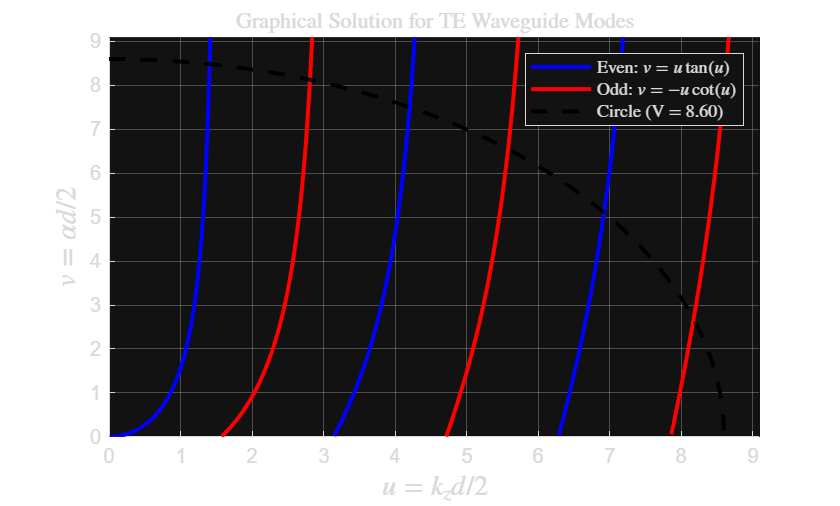


% 3. Define the u-axis vector (u = kz * d / 2)
% We search for solutions between 0 and V
u = linspace(0.01, V + 0.5, 1000); 

% 4. Calculate the transcendental functions for the modes
% Even modes: v = u * tan(u)
v_even = u .* tan(u);
v_even(v_even < 0 | v_even > V + 1) = NaN; % Filter for physical/plottable values

% Odd modes: v = -u * cot(u)
v_odd = -u ./ tan(u);
v_odd(v_odd < 0 | v_odd > V + 1) = NaN; % Filter for physical/plottable values

% 5. Define the circle constraint: u^2 + v^2 = V^2
u_circle = linspace(0, V, 500);
v_circle = sqrt(V^2 - u_circle.^2);

% 6. Plot the Graphical Solution
figure('Color', 'w');
hold on;
plot(u, v_even, 'b', 'LineWidth', 2, 'DisplayName', 'Even: $v = u \tan(u)$');
plot(u, v_odd, 'r', 'LineWidth', 2, 'DisplayName', 'Odd: $v = -u \cot(u)$');
plot(u_circle, v_circle, 'k--', 'LineWidth', 2, 'DisplayName', sprintf('Circle (V = %.2f)', V));

% Formatting the plot
grid on;
xlabel('$u = k_z d / 2$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$v = \alpha d / 2$', 'Interpreter', 'latex', 'FontSize', 14);
title('Graphical Solution for TE Waveguide Modes', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'northeast');
axis([0 V+0.5 0 V+0.5]);

Looking at your graphical solution for the waveguide modes, how many odd and even modes are supported for $\omega =\frac{3c}{d}$?

For V=5, there are a total of **4 supported modes**:

- **2 Even modes** (m = 0, 2)

- **2 Odd modes** (m = 1, 3)


$$$$M = \lceil \frac{2V}{\pi} \rceil$$For $V = 5$:$$M = \lceil \frac{10}{\pi} \rceil \approx \lceil 3.18 \rceil = 4$$$$


#### (c) Numerical solution: Solve for and plot the dispersion relation

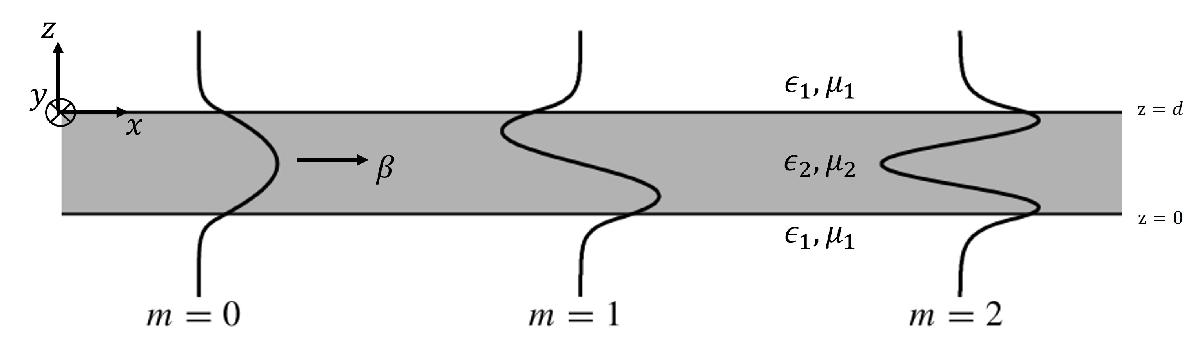

**Figure 3** In the waveguide dispersion plot, we plot $\beta =k_x$ as a function of $\omega \;\ldotp$ Here, the first three modes are illustrated: m=0 is the first even mode and m=1 is the first odd mode.

Now you will fill in the functions findEvenMode.m and findOddMode.m to solve for the dispersion relation of the waveguide system for the even and odd mode cases. Once you fill in these functions you should solve for and plot the modes in a $k_x \;\textrm{vs}\;\omega \;$plot. You can non-dimensionalize your plot if you would like.

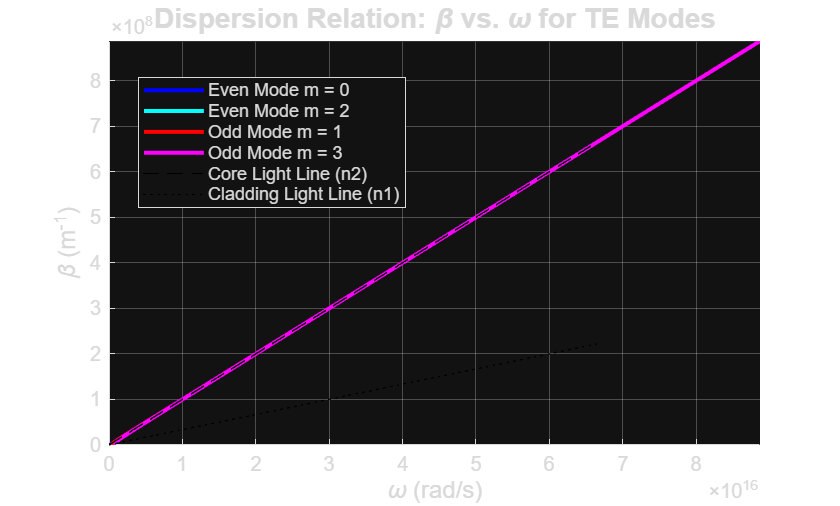

%% Solve for the even and odd modes

clear;

% Define the refractive index of the core and cladding
n2      = 3; % core [1]
n1      = 1; % cladding [1]
c       = 3e8; % [m/s]

% Diameter of the core
d       = 1.5e-6; % [m]

% === TYPE YOUR CODE BELOW === %

figure('Color', 'w');
hold on;

% 1. Call findEvenMode.m for the first two even modes (m = 0, 2)
even_modes = [0, 2];
colors_even = {'b', 'cyan'};

for i = 1:length(even_modes)
    [omega_e, beta_e] = findEvenMode(even_modes(i), d, n1, n2);
    plot(omega_e, beta_e, colors_even{i}, 'LineWidth', 2, ...
        'DisplayName', ['Even Mode m = ', num2str(even_modes(i))]);
end

% 2. Call findOddMode.m for the first two odd modes (m = 1, 3)
odd_modes = [1, 3];
colors_odd = {'r', 'magenta'};

for i = 1:length(odd_modes)
    [omega_o, beta_o] = findOddMode(odd_modes(i), d, n1, n2);
    plot(omega_o, beta_o, colors_odd{i}, 'LineWidth', 2, ...
        'DisplayName', ['Odd Mode m = ', num2str(odd_modes(i))]);
end

% 3. Plot light lines for reference
% Beta = n * omega / c
omega_ref = linspace(0, max(omega_e), 100);
plot(omega_ref, n2 * omega_ref / c, 'k--', 'DisplayName', 'Core Light Line (n2)');
plot(omega_ref, n1 * omega_ref / c, 'k:', 'DisplayName', 'Cladding Light Line (n1)');

% Formatting the dispersion plot
xlabel('\omega (rad/s)', 'FontSize', 12);
ylabel('\beta (m^{-1})', 'FontSize', 12);
title('Dispersion Relation: \beta vs. \omega for TE Modes', 'FontSize', 14);
legend('Location', 'best');
grid on;
axis tight;

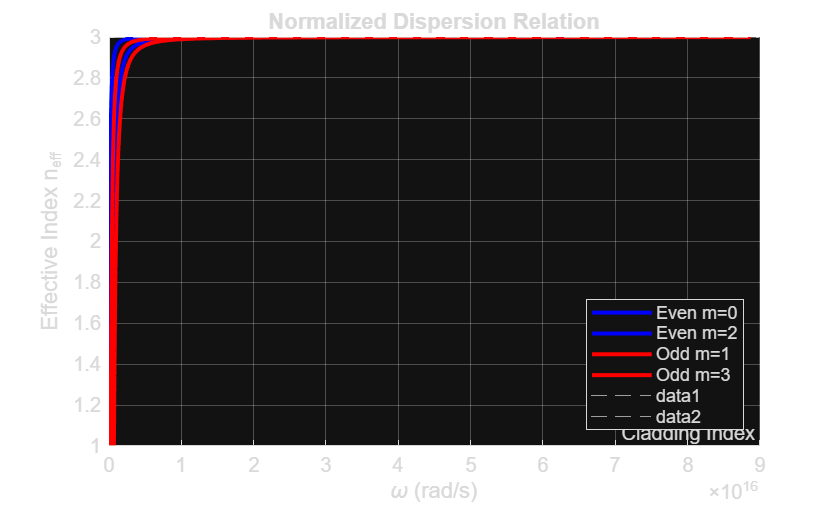


% Optional: Plotting n_eff instead of beta for a clearer view of guidance
figure('Color', 'w');
hold on;
for m = [0, 2]
    [w, b] = findEvenMode(m, d, n1, n2);
    plot(w, b./(w/c), 'b', 'LineWidth', 2, 'DisplayName', ['Even m=', num2str(m)]);
end
for m = [1, 3]
    [w, b] = findOddMode(m, d, n1, n2);
    plot(w, b./(w/c), 'r', 'LineWidth', 2, 'DisplayName', ['Odd m=', num2str(m)]);
end
yline(n1, '--', 'Cladding Index');
yline(n2, '--', 'Core Index');
xlabel('\omega (rad/s)');
ylabel('Effective Index n_{eff}');
title('Normalized Dispersion Relation');
legend('Location', 'southeast');
grid on;

## Part 3 (extra credit)

#### Using the dispersion diagram solutions for the even and odd modes, plot the electrical field as a function of z for 

#### (a) the first even mode and (b) the second odd mode:

We assume a solution for the eletric field in the waveguide system of the form


$$E_y \left(x,z\right)={\hat{y} \;E}_0 \left\lbrace \begin{array}{ll}
\cos \left(k_z d+\frac{\phi }{2}\right)e^{-\gamma_z \;\left(z-d\right)} e^{i\beta x}  & z\ge d\\
\cos \left(k_z z+\frac{\phi }{2}\;\right)e^{i\beta x}  & 0\le z\le d\\
\cos \left(-\frac{\phi }{2}\right)e^{\gamma_z z\;} e^{i\beta x}  & z\le 0
\end{array}\right.$$


where $k_z$ is the wave vector in the z-direction inside the slab and $\gamma_z$ is the wave vector in the z-direction outside of the slab that is exponentially decaying.

Briefly explain why these are the forms of the solutions that are assumed:

    [TYPE ANSWER HERE]

%% Create code here to plot the E-field for (a) and (b)

% === TYPE YOUR CODE BELOW === %
